# Ca Vid Main

addpath('Cheer/Ca Vids')
%filename=input('Enter a video filename: ','s');
filename='msCam1.avi';
comp=readvid(filename);

## Detect Traces

[traces,centers,radii,c]=cadet(comp);

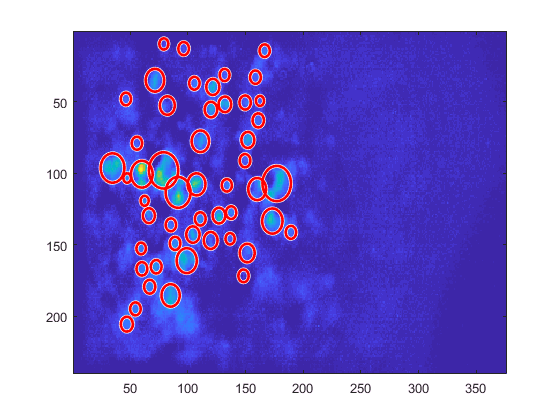


imagesc(max(c,[],3))
hold on
viscircles(centers(:,:),radii(:,:));
hold off

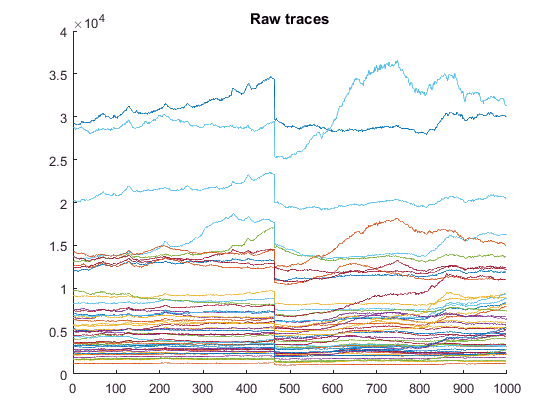


fig1=figure;
title('Raw traces')
hold on
for i = 1:size(traces,1)
    plot(traces(i,:))
end
hold off

## Process Traces

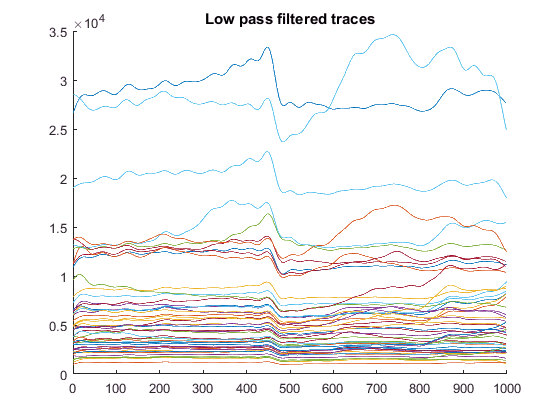

[neurons,calciumtransients,clusters]=sigpro(traces,centers);

fig2=figure;
hold on
for i=1:size(traces,1)
    plot(traces(i,:)-calciumtransients(i,:)+i*100) 
end
title('Low pass subrated traces')
hold off 

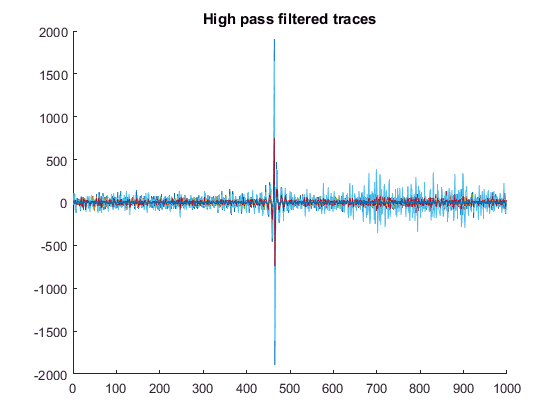


fig=figure;
hold on
for i=1:size(traces,1)
    plot(neurons(i,:))
    title('High pass filtered traces')
end
hold off

## Wavelet Analysis

n=3;
wc=wavedec3(comp,n,'db1');
A = cell(1,n);
D = cell(1,n);
for k = 1:n
    A{k} = waverec3(wc,'a',k);   % Approximations (low-pass components)
    D{k} = waverec3(wc,'d',k);   % Details (high-pass components)
end

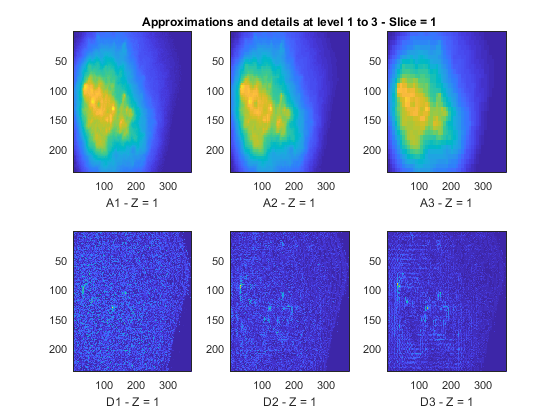

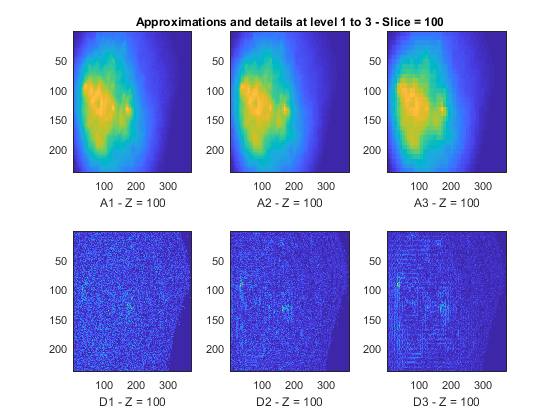

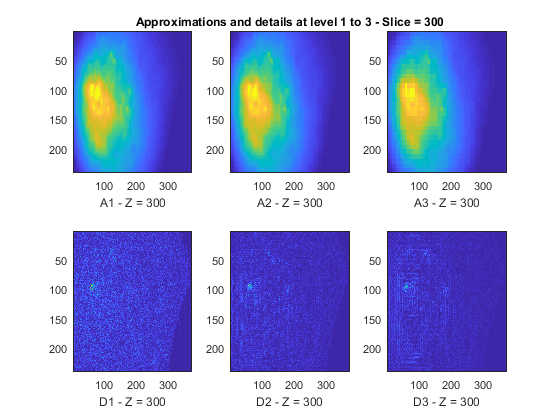

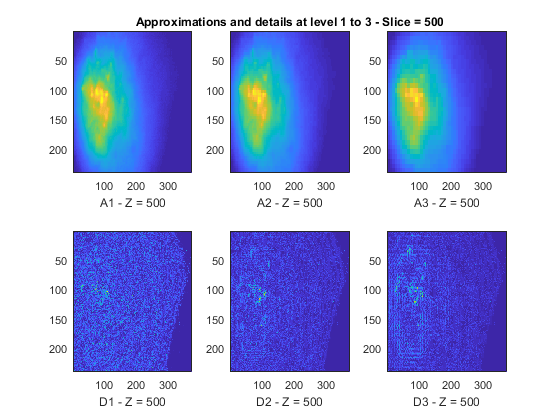

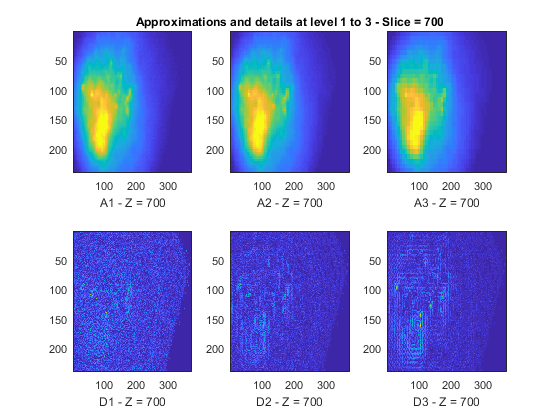

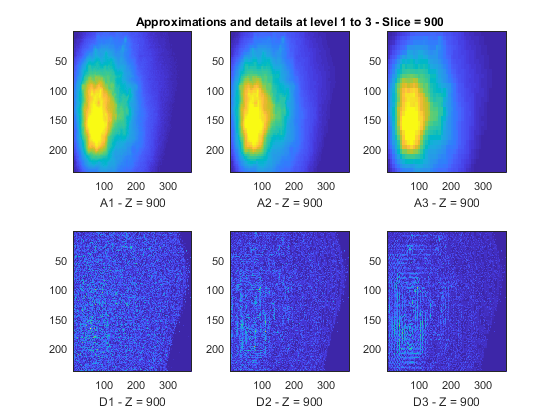


nbIMG = 6;
idxImages_New = [1 100 300 500 700 900];
for ik = 1:nbIMG
    j = idxImages_New(ik);
    figure('DefaultAxesXTick',[],'DefaultAxesYTick',[],...
        'DefaultAxesFontSize',8,'Color','w')
    %colormap(map)
    for k = 1:n
        labstr = [int2str(k) ' - Z = ' int2str(j)];
        subplot(2,n,k);
        image(A{k}(:,:,j));
        xlabel(['A' labstr]);
        if k==2
        	title(['Approximations and details at level 1 to 3 - Slice = ' num2str(j)]);
        end
        subplot(2,n,k+n);
        imagesc(abs(D{k}(:,:,j)));
        xlabel(['D' labstr]);
    end
end